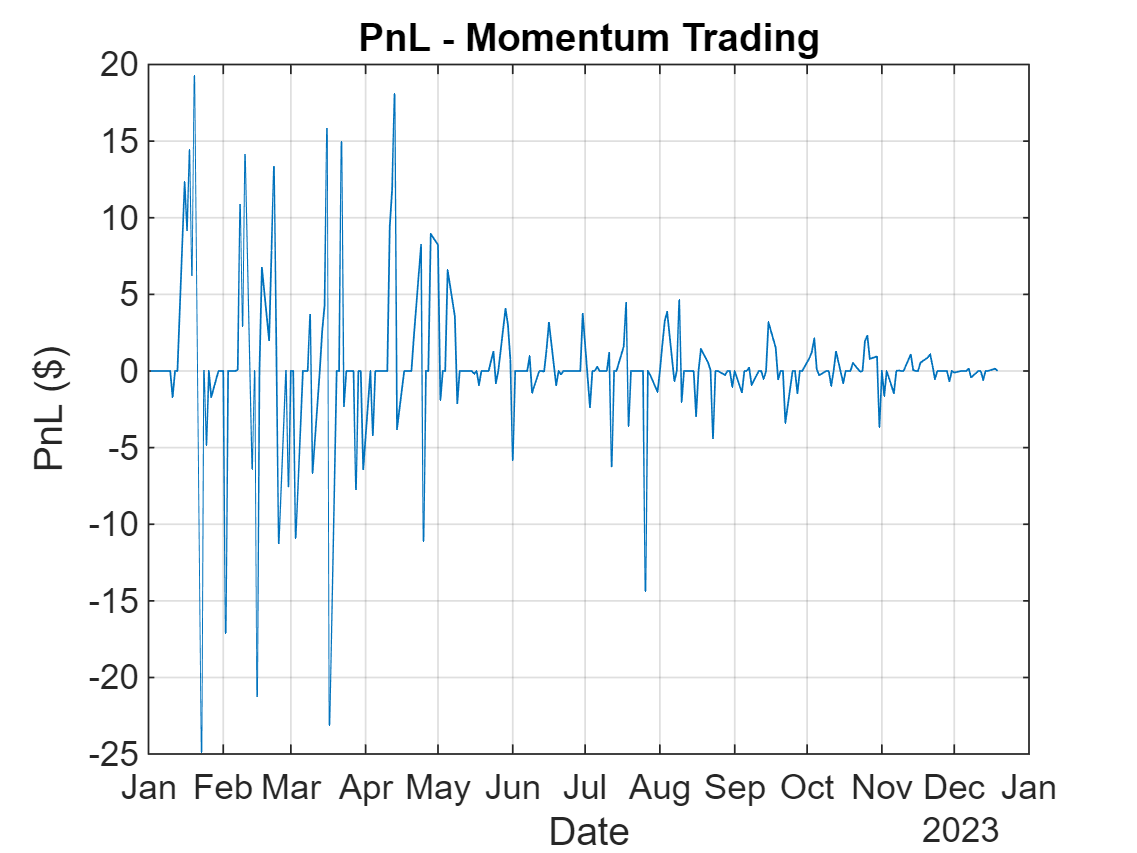

% Parameters
numDays = 252;
InitialPrice = 120;
Volatility = 0.1;
Drift = 0.0001;
OpenVolatility = 0.01;

% Generate dates excluding weekends
startDate = datetime(2023,1,1);
endDate = startDate + caldays(365);
allDates = startDate:endDate;
tradingDates = allDates(~(weekday(allDates) == 1 | weekday(allDates) == 7));
tradingDates = tradingDates(1:numDays);

rng("default");
openPrices = zeros(numDays, 1);
closePrices = zeros(numDays, 1);
openPrices(1) = InitialPrice;
closePrices(1) = InitialPrice * (1 + Drift + Volatility * randn());

for t = 2:numDays
    openPrices(t) = closePrices(t-1) * (1 + OpenVolatility * randn());
    closePrices(t) = openPrices(t) * (1 + Drift + Volatility * randn());
end

stockData = table(tradingDates', openPrices, closePrices, ...
                  'VariableNames', {'Date', 'Open', 'Close'});

dis_pd = py.pandas.DataFrame(stockData);
%Trading Strategy selection
TradingStrategy = 'Momentum';
if contains('Momentum',TradingStrategy)
    PnL_dis = py.trading_fnx.momentum(dis_pd);
elseif contains('Mean Reversion',TradingStrategy)
    PnL_dis = py.trading_fnx.mean_rev(dis_pd);
else
    PnL_dis = py.trading_fnx.sma(dis_pd);
end
PnL_distable = table(PnL_dis);
plot(PnL_distable.Date,table2array(PnL_distable(:,4))); grid on; xlabel('Date'); ylabel('PnL ($)'); title(strcat("PnL - ",TradingStrategy,' Trading'));

disp(strcat('Max PnL ($): ',string(max(table2array(PnL_distable(:,4))))))

Max PnL ($):19.2349


disp(strcat('Min PnL ($): ',string(min(table2array(PnL_distable(:,4))))))

Min PnL ($):-24.8603


disp(strcat('Average PnL ($): ',string(mean(table2array(PnL_distable(:,4))))))

Average PnL ($):0.22297


disp(strcat('Cumulative PnL ($): ',string(sum(table2array(PnL_distable(:,4))))))

Cumulative PnL ($):56.1883


disp(strcat('Sharpe Ratio: ',string(sqrt(252)*mean(table2array(PnL_distable(:,4)))/std(table2array(PnL_distable(:,4))))))

Sharpe Ratio:0.72869


disp(strcat('Average Trade ($): ',string(sum(table2array(PnL_distable(:,4)))/sum(table2array(PnL_distable(:,5))))))

Average Trade ($):0.43897


clear Drift InitialPrice OpenVolatility PnL_dis PnL_distable TradingStrategy Volatility allDates closePrices dis_pd endDate numDays openPrices startDate stockData t tradingDates;